# Plot Turbulence Empirical RSN filt (0.08-0.008)

Plot results from the empirical analysis: turbulence, information flow, information cascade and information transfer obtained in turbulence_empirical_RSN.mlx. 

TBI dataset from OpenNeuro: [https://openneuro.org/datasets/ds000220/versions/1.0.0/file-display/dataset_description.json](https://openneuro.org/datasets/ds000220/versions/1.0.0/file-display/dataset_description.json)

## Load results

clear all
data_path='/Volumes/LASA/TBI_project/TBI_openneuro/timeseries/outputs/Turbulence_28_03_2022/';
output_path='/Volumes/LASA/TBI_project/TBI_openneuro/timeseries/outputs/Turbulence_28_03_2022/figures/turbu_all_OpenNeuroTBI_N24_con1_nofilt/';
addpath '/Users/noeliamartinezmolina/Documents/GitHub/TBI_turbulence_openneuro_current_code/helper functions'
lambda={'0.27','0.24','0.21','0.18','0.15','0.12','0.09','0.06','0.03','0.01'};
cond = {'Controls','Patients'};
cd(data_path)
results = load(sprintf('turbu_all_measurements_nofilt_con1.mat'));
idx_con=[1:1:12]; idx_pat=[13:1:24];
Turbu_con= results.Turbulence_global_sub(:,idx_con);
Turbu_pat= results.Turbulence_global_sub(:,idx_pat);
Turbu_RSN_con= results.TurbulenceRSN_sub(:,idx_con,:);
Turbu_RSN_pat= results.TurbulenceRSN_sub(:,idx_pat,:);
Info_flow_con = results.TransferLambda_sub(:,idx_con);
Info_flow_pat = results.TransferLambda_sub(:,idx_pat);
Info_cascade_con = results.InformationCascade_sub(:,idx_con);
Info_cascade_pat = results.InformationCascade_sub(:,idx_pat);
Info_transfer_con = results.Transfer_sub(:,idx_con);
Info_transfer_pat = results.Transfer_sub(:,idx_pat);
cd(output_path)


## Plot global Turbulence

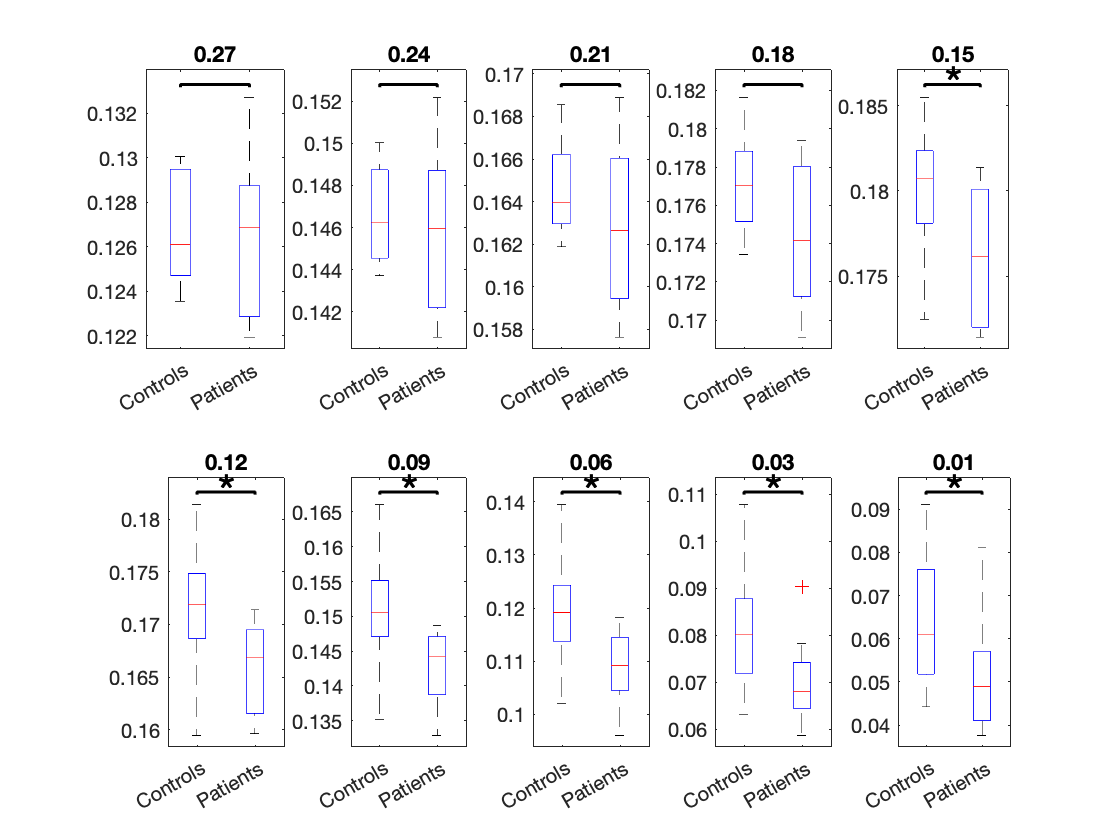

figure
for lamb=1:length(lambda)
    subplot(2,5,lamb)
    C = {Turbu_con(lamb,:) , Turbu_pat(lamb,:)};    
    maxNumEl = max(cellfun(@numel,C));
    Cpad = cellfun(@(x){padarray(x(:),[maxNumEl-numel(x),0],NaN,'post')}, C);
    Cmat = cell2mat(Cpad);
    boxplot(Cmat,'Labels',cond)
    title(lambda{lamb})
    
    [~,pval] = ttest(Turbu_con(lamb,:),Turbu_pat(lamb,:)); % paired t Test
    p(1,lamb)=pval; clear pval
    H=sigstar({[1,2]},p(1,lamb));
end
print('Turbulence Global Open Neuro TBI (N=24) filt','-dpng')

close()

## Plot turbulence by RSN

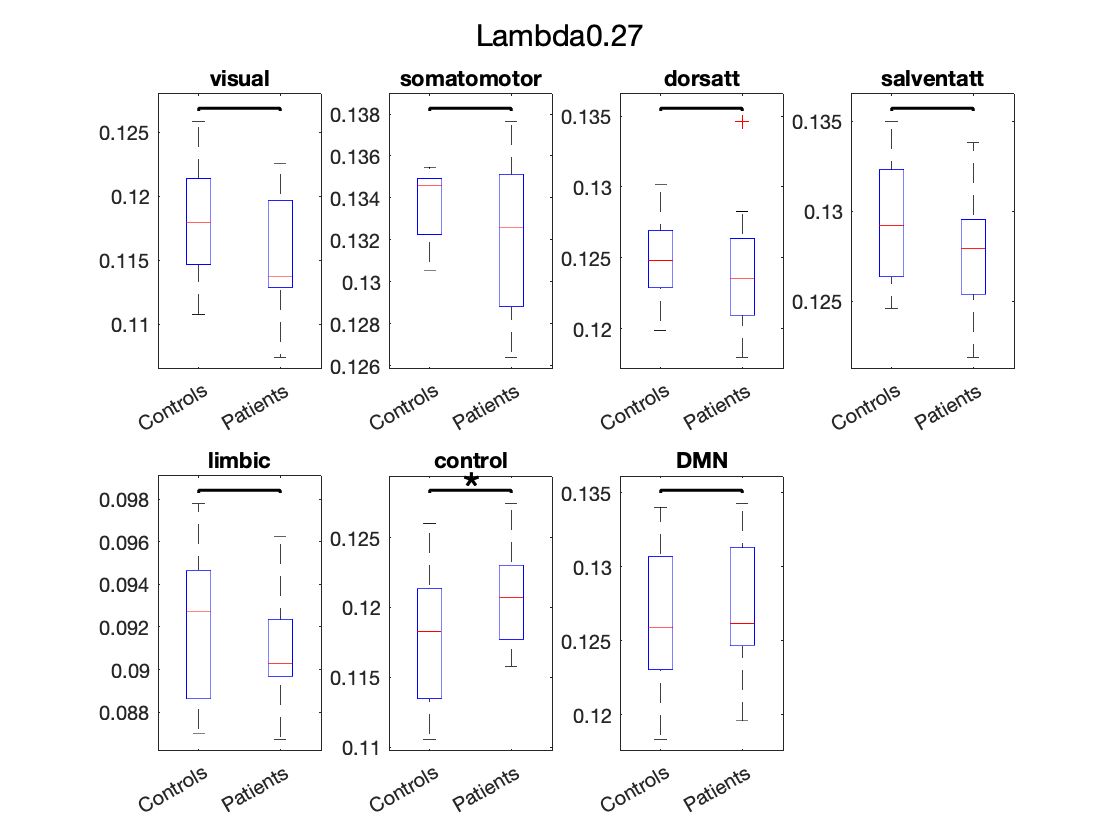

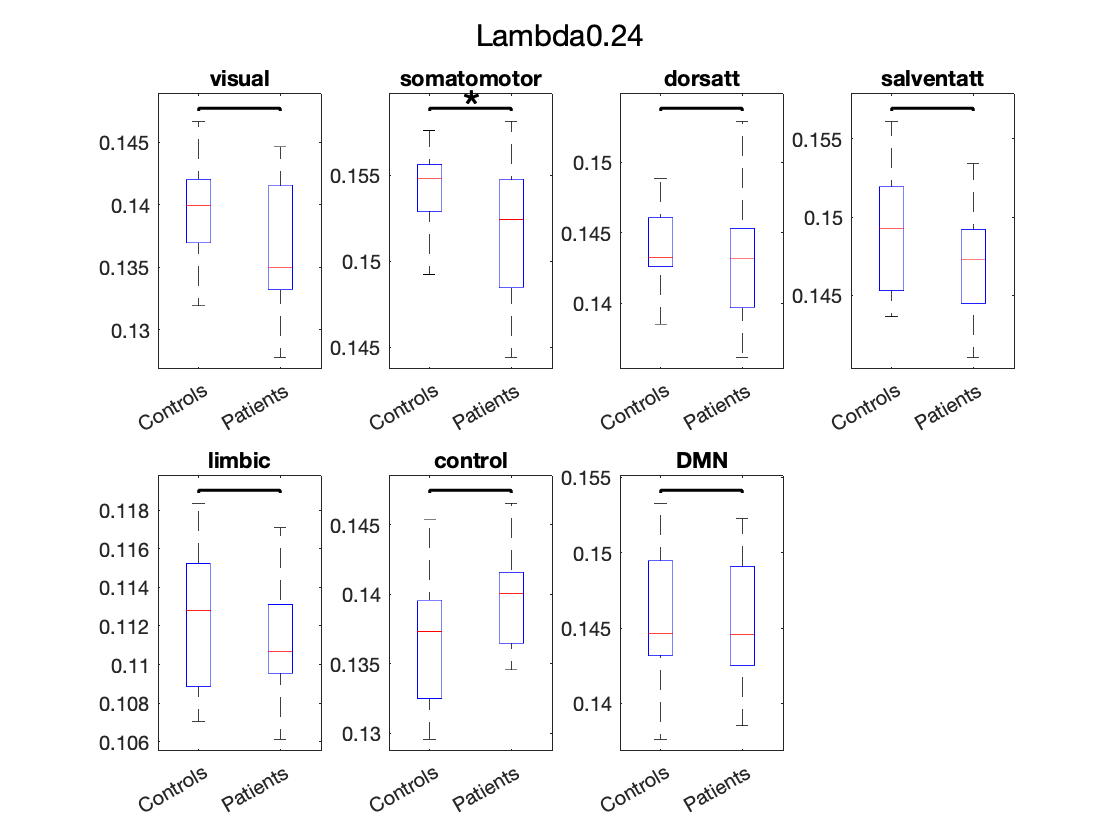

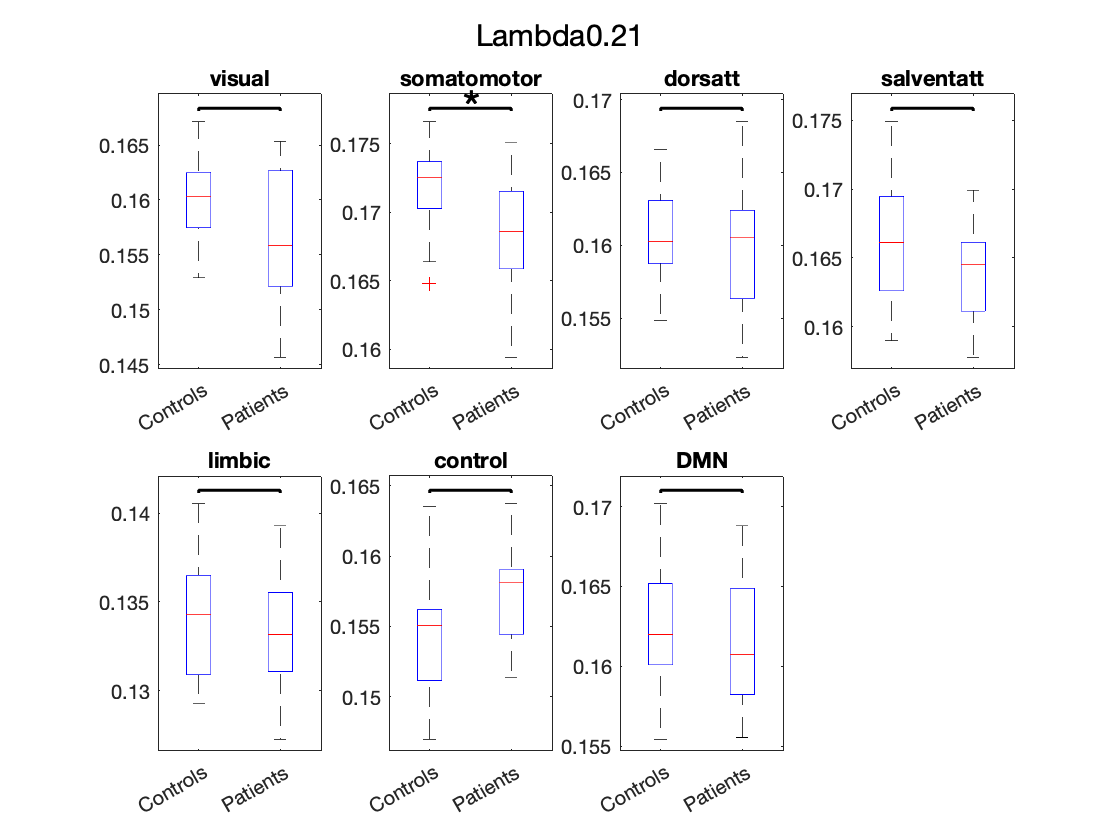

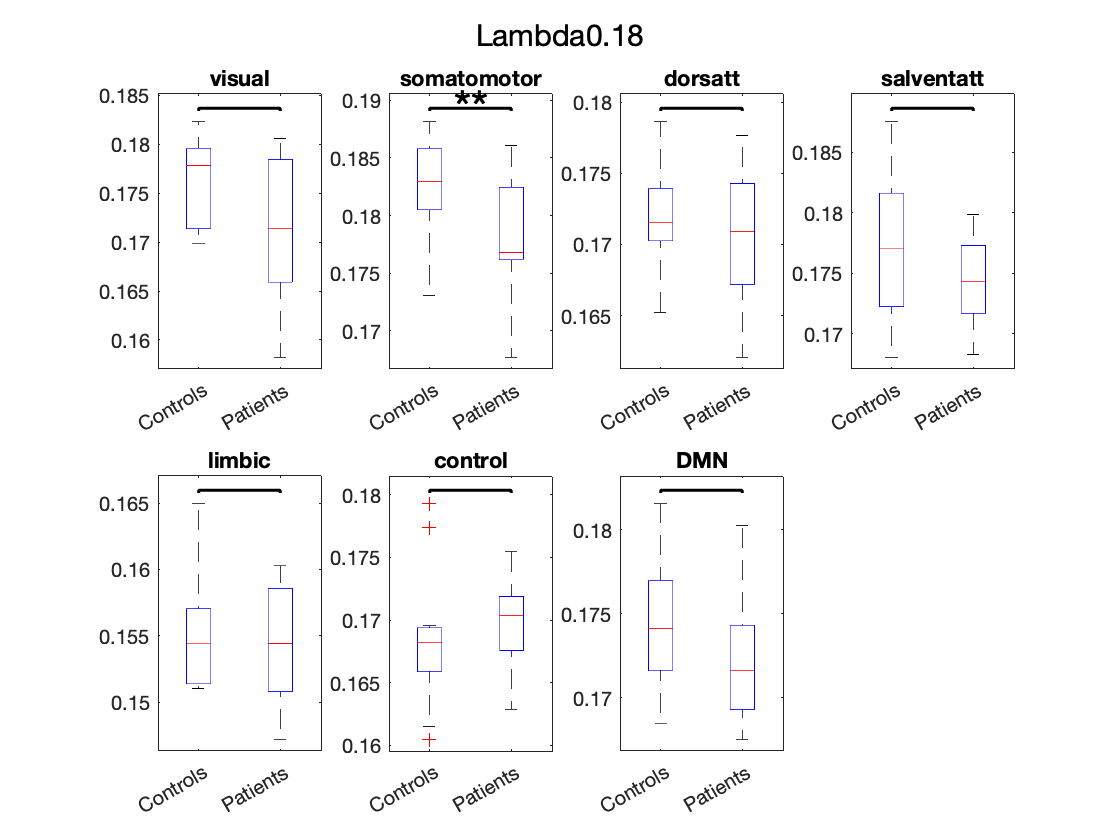

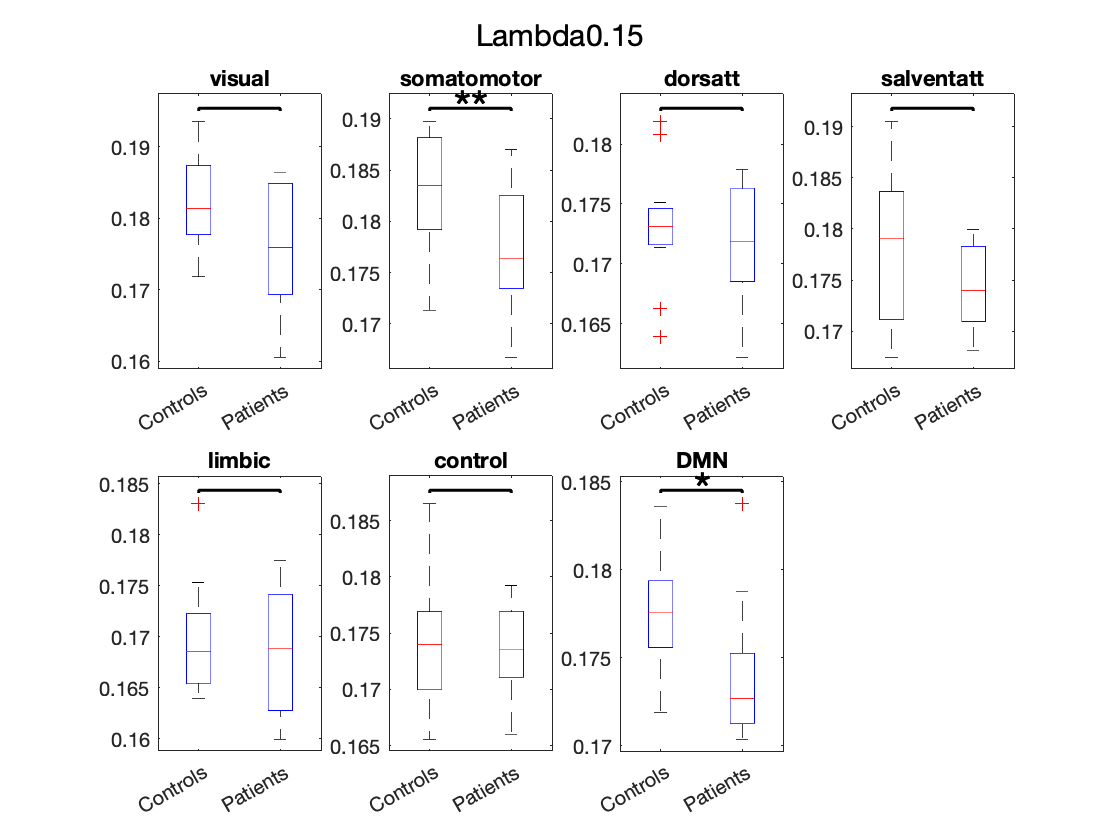

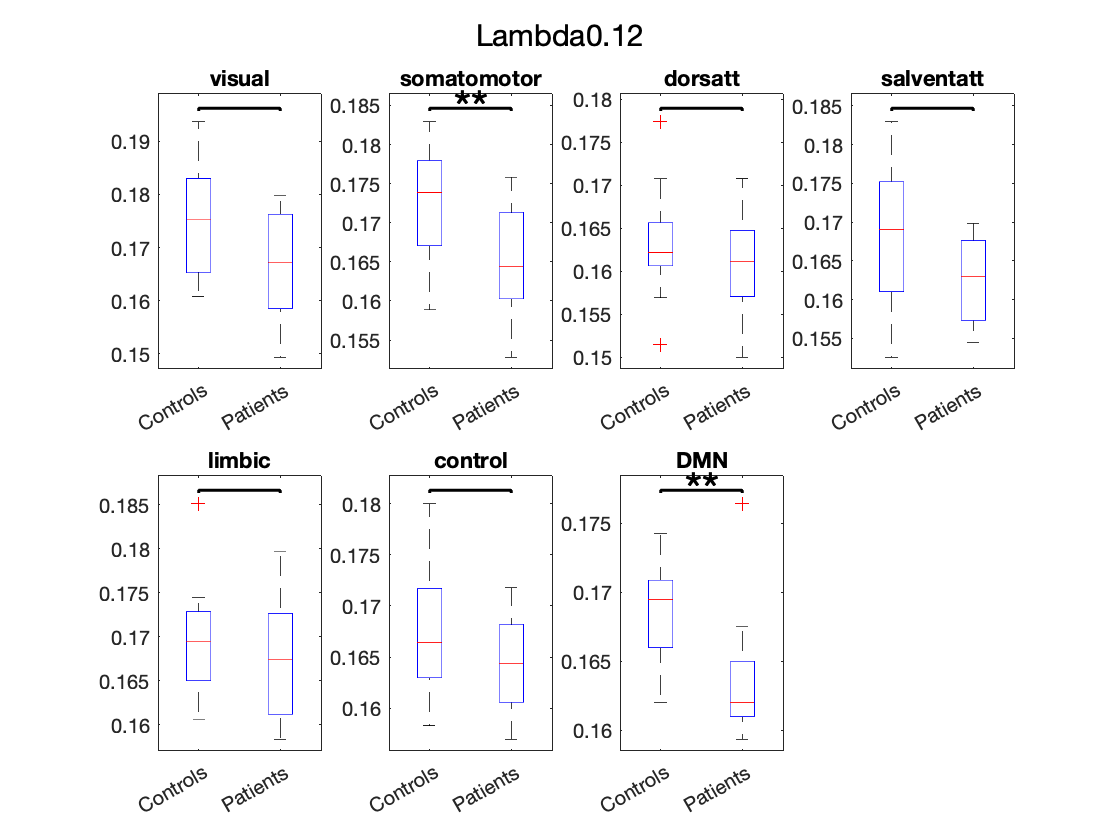

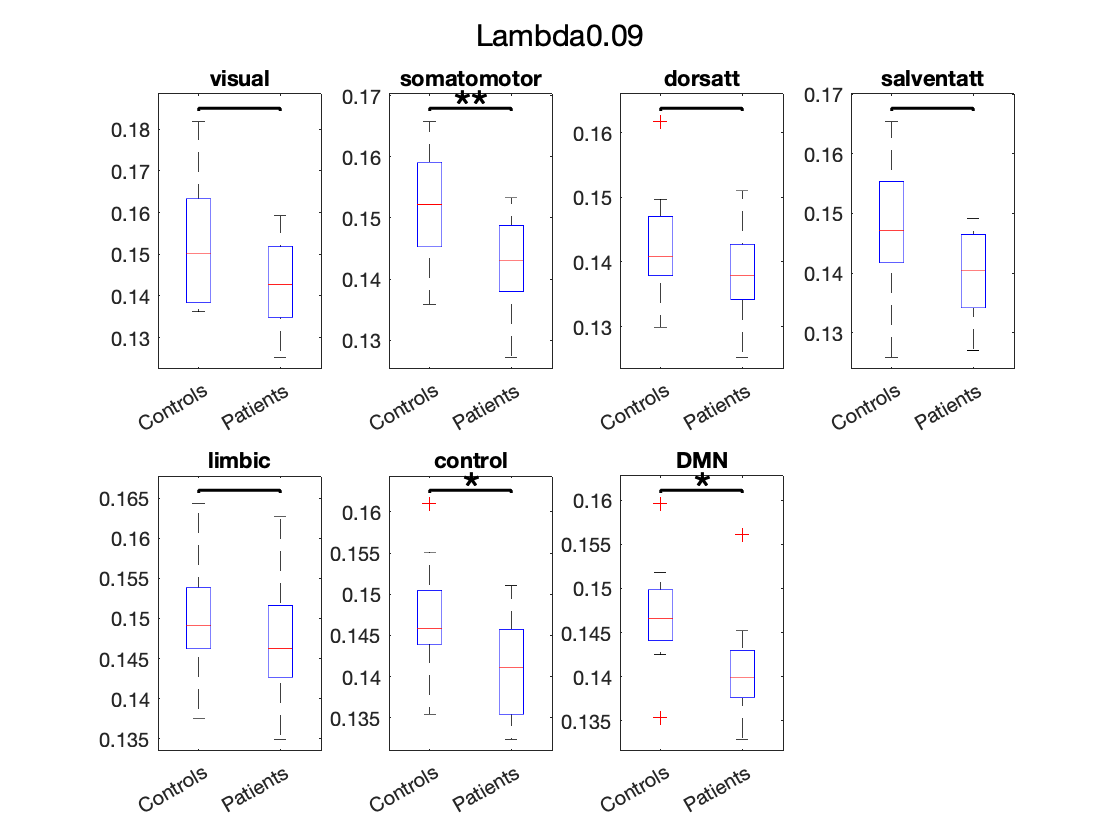

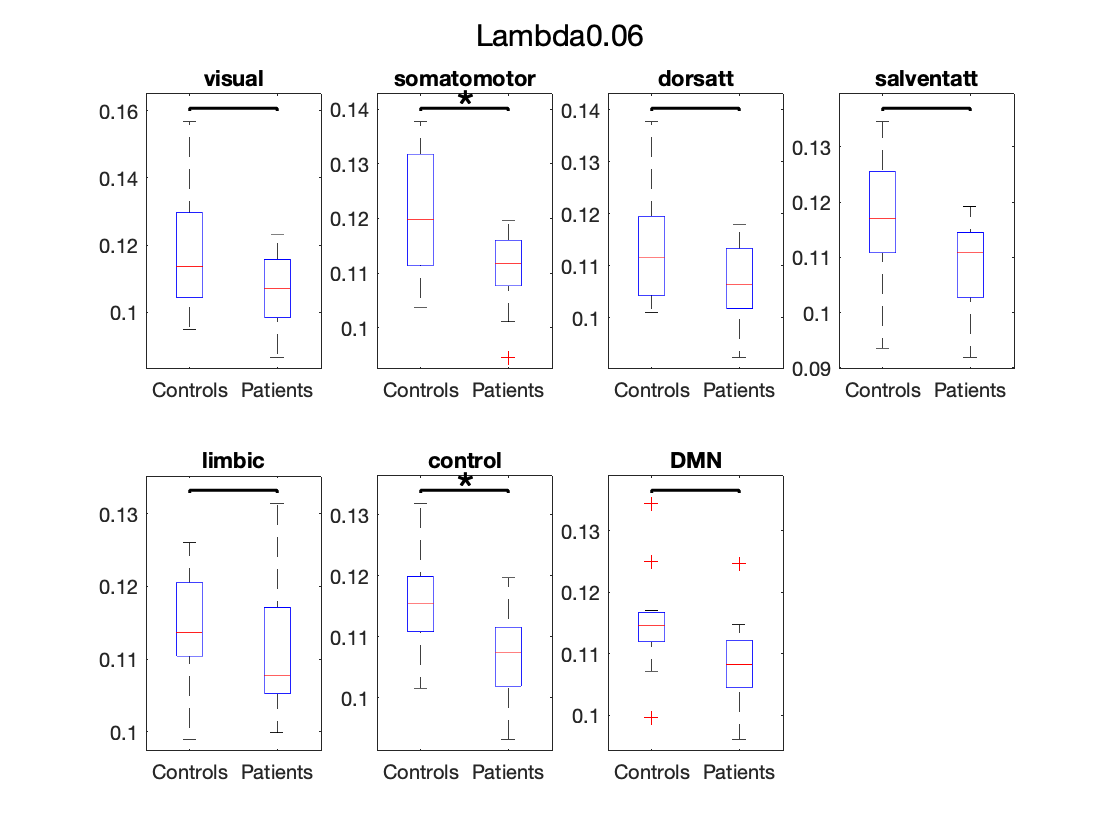

Rsns = {'visual', 'somatomotor','dorsatt','salventatt','limbic','control','DMN'};
for lamb=1:length(lambda)
    figure
    sgtitle (['Lambda' char(lambda(lamb))])
    for jj=1:7 %Loop for networks
        subplot(2,4,jj)
        C = {Turbu_RSN_con(lamb,:,jj) , Turbu_RSN_pat(lamb,:,jj)};
        maxNumEl = max(cellfun(@numel,C));
        Cpad = cellfun(@(x){padarray(x(:),[maxNumEl-numel(x),0],NaN,'post')}, C);
        Cmat = cell2mat(Cpad);
        boxplot(Cmat,'Labels',cond)
        title(Rsns{jj})
        
        [~,pval] = ttest(Turbu_RSN_con(lamb,:,jj),Turbu_RSN_pat(lamb,:,jj)); % paired t Test
        p(1,jj)=pval; clear pval
        H=sigstar({[1,2]},p(1,jj));
    end
    print(['Turbulence RSN Open Neuro TBI (N=24) filt lambda' num2str(lamb)],'-dpng')
end

close()

## Plot information flow

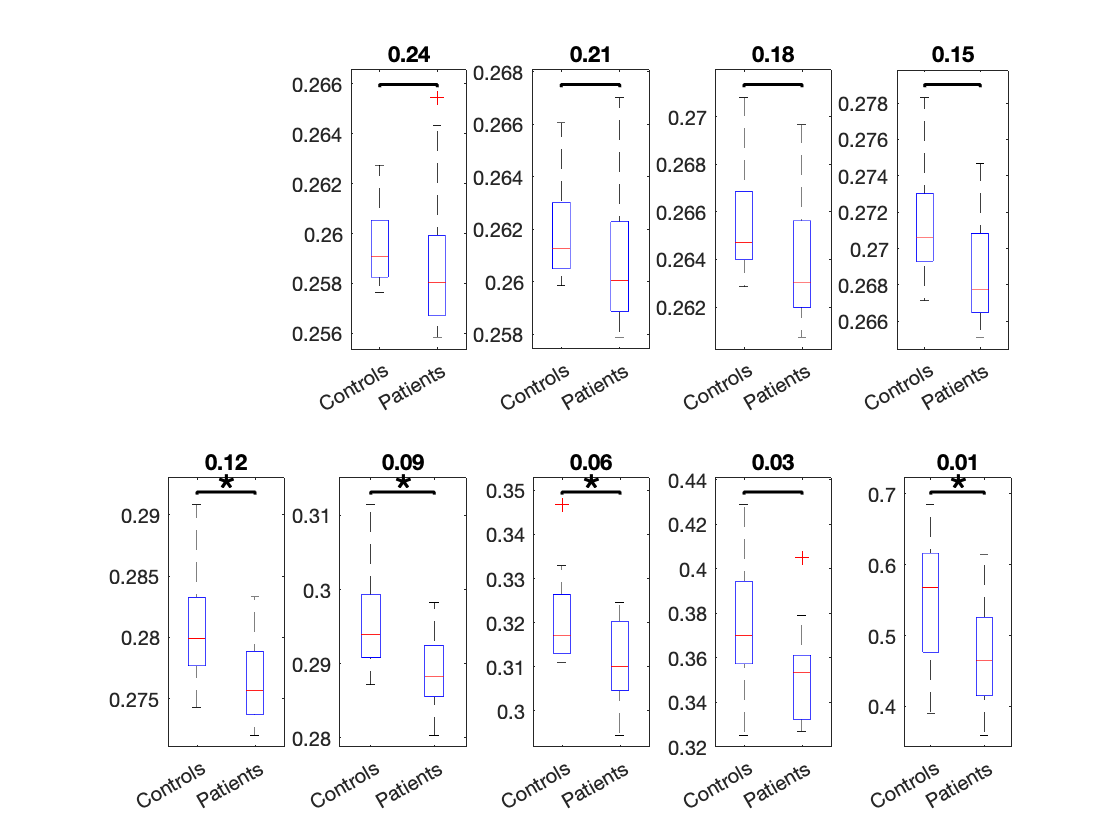

figure
for lamb=2:length(lambda)
    subplot(2,5,lamb)
    C = {Info_flow_con(lamb,:) , Info_flow_pat(lamb,:)};    
    maxNumEl = max(cellfun(@numel,C));
    Cpad = cellfun(@(x){padarray(x(:),[maxNumEl-numel(x),0],NaN,'post')}, C);
    Cmat = cell2mat(Cpad);
    boxplot(Cmat,'Labels',cond)
    title(lambda{lamb})
    
    [~,pval] = ttest(Info_flow_con(lamb,:),Info_flow_pat(lamb,:)); % paired t Test
    p(1,lamb)=pval; clear pval
    H=sigstar({[1,2]},p(1,lamb));
end
print('Info Flow Open Neuro TBI (N=24) filt','-dpng')

close()

## Plot information cascade

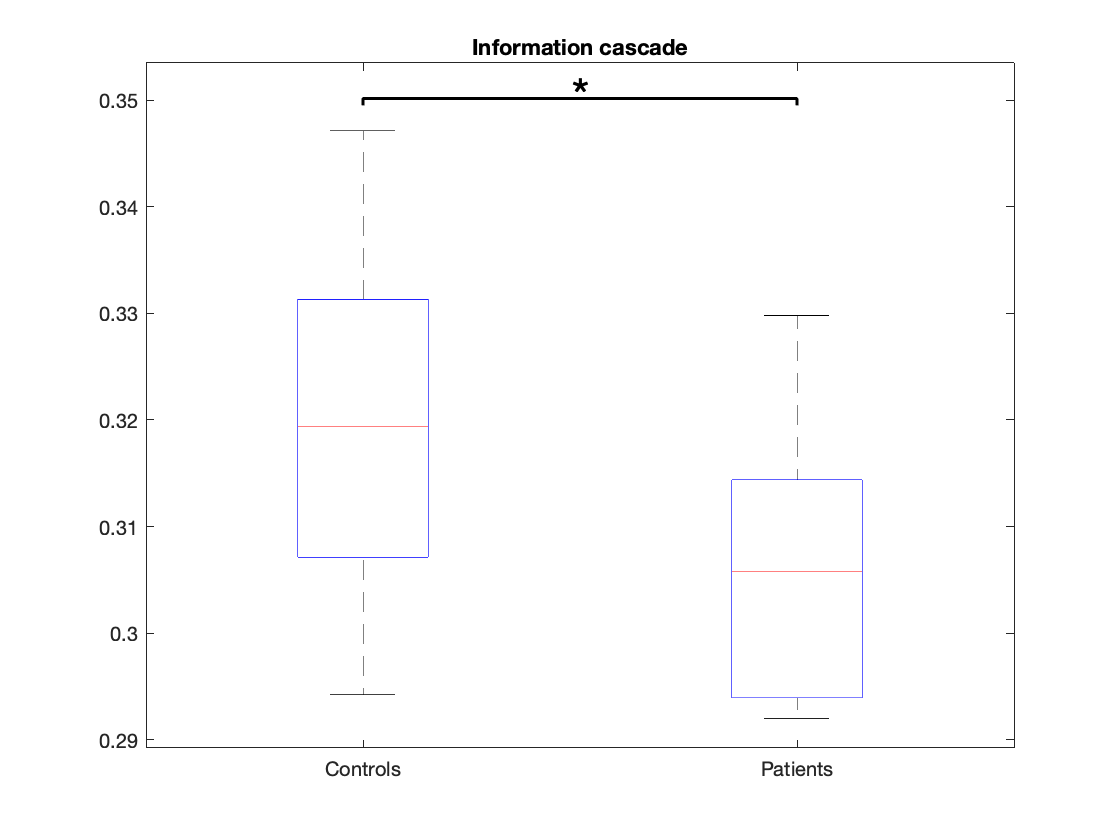

figure
C = {Info_cascade_con, Info_cascade_pat};
maxNumEl = max(cellfun(@numel,C));
Cpad = cellfun(@(x){padarray(x(:),[maxNumEl-numel(x),0],NaN,'post')}, C);
Cmat = cell2mat(Cpad);
boxplot(Cmat,'Labels',cond)
title('Information cascade')

[~,pval] = ttest(Info_cascade_con,Info_cascade_pat); % paired t Test
H=sigstar({[1,2]},pval);
print(['Info Cascade Open Neuro TBI (N=24) filt lambda' num2str(lamb)],'-dpng')

close()

## Plot information transfer

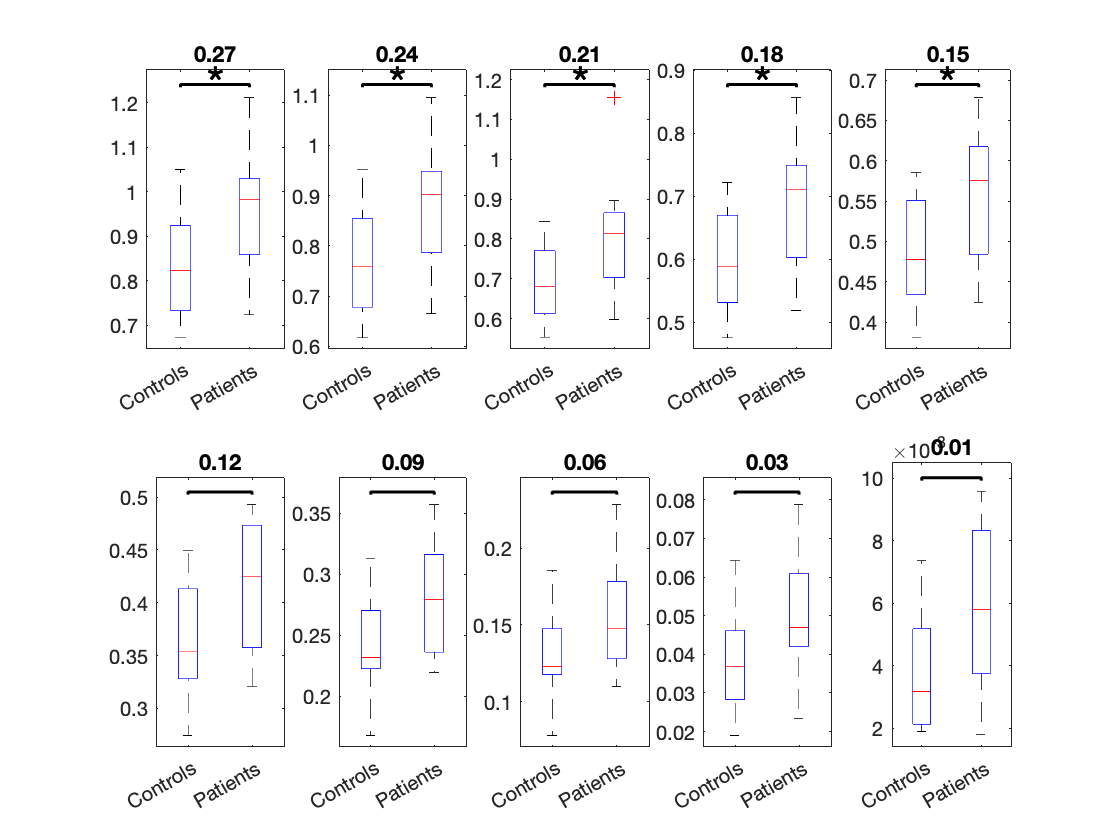

figure
for lamb=1:length(lambda)
    subplot(2,5,lamb)
    C = {Info_transfer_con(lamb,:) , Info_transfer_pat(lamb,:)};    
    maxNumEl = max(cellfun(@numel,C));
    Cpad = cellfun(@(x){padarray(x(:),[maxNumEl-numel(x),0],NaN,'post')}, C);
    Cmat = cell2mat(Cpad);
    boxplot(Cmat,'Labels',cond)
    title(lambda{lamb})
    
    [~,pval] = ttest(Info_transfer_con(lamb,:),Info_transfer_pat(lamb,:)); % paired t Test
    p(1,lamb)=pval; clear pval
    H=sigstar({[1,2]},p(1,lamb));
end
print(['Info Transfer Open Neuro TBI (N=24) filt lambda' num2str(lamb)],'-dpng')

close()